# Regressing a Static Model

**B(i) Using a correlation matrix to visualise the significance of the variables in the dataset. **

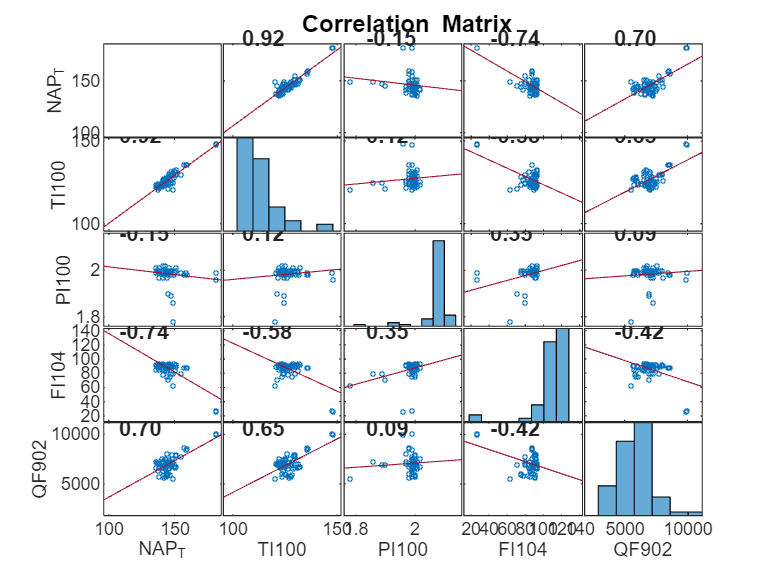

figure;
corrplot(plotT95.Variables, VarNames=variableNames)

**B(ii) What Variable most strongly correlates to the Naphtha T95**

**TI1006 - ** Strongly correlates most with the Naphtha T95 with a value of 0.92. Below is a talble of the variables and their correlation with Naphtha T95 in ascending order (and absolute values).

Variable      Correlation

TI1006          0.92

FI1048         -0.74

QF9020        0.70

PI1003         -0.15

**B(iii) What process variables appear to be least important for predicting Naphtha T95? Could it be because of data quality**

PI1003 has the least correlation with Naphtha T95 which shows its the least important for predicting Naphtha T95. 

Since the variables correlate with each other according to physics, that is, an increase in pressure will cause increase in temperature and vice versa. Also, an increase in flow to the chamber will increase the temperature. We can say the effect is due to the quality of data as discussed in task A(iii). Pressure data has little variance, meaning it will be less useful in modelling. 

**B(iv) Which process variables are most closely correlated with each other? Should we remove a variable because it is strongly related to another or is it only a partial correlation?**

**TI1006 - QF**9020 0.65

**TI1006 - FI1048  **-0.58

Temperaature is closely correlated with Flow and QF9020. The variable should not be removed as it is only a partial correlation. Other forms of transformation can be applied to the inputs to reduce their dependence or correlation with each other.

**B(v) Create a linear regression model using the process variables to predict the naphtha T95, note your coefficients for each parameter.**

model = fitlm(variables(:,2:end),plotT95.NAP_T95,"linear");
model

model = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)       81.441        14.176     5.7448     4.141e-07
    x1                1.1653        0.0732     15.919    3.0137e-22
    x2               -42.448        7.8478    -5.4089    1.4193e-06
    x3              -0.12096      0.029159    -4.1484      0.000117
    x4             0.0016042    0.00037432     4.2855    7.3968e-05


Number of observations: 60, Error degrees of freedom: 55
Root Mean Squared Error: 1.94
R-squared: 0.952,  Adjusted R-Squared: 0.948
F-statistic vs. constant model: 271, p-value = 1.69e-35

modelCoefficients = model.Coefficients.Estimate

modelCoefficients =    81.4406
    1.1653
  -42.4478
   -0.1210
    0.0016


[T P, F, Q] = variables(:,2:end);

Insufficient number of outputs from right hand side of equal sign to satisfy assignment.